% Initializing script
clc, clf, clear

constants;

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i)/P_c_ref, 1, 1]);
    total_mass_A_t(i) = calc_objective([1, A_t(i)/A_t_ref, 1]);
    total_mass_A_e(i) = calc_objective([1, 1, A_e(i)/A_e_ref]);
end

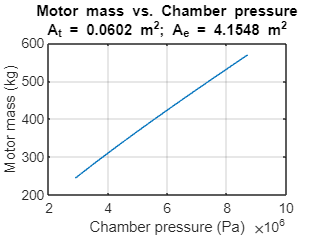

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

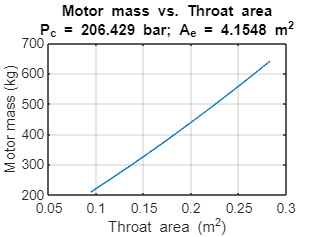


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

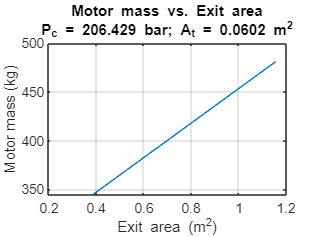


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            x_scaled = scale([P_c(i), A_t(j), A_e(k)], x_ref);
            total_mass_val(i, j, k) = calc_objective(x_scaled);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints(x_scaled);
        end
    end
end

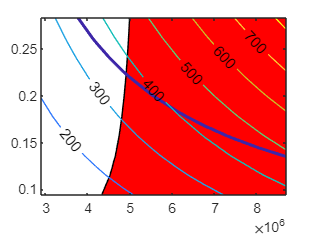

% Example plot
clf
i = 4;
contourf(P_c, A_t, ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(P_c, A_t, eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(P_c, A_t, total_mass_val(:,:, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [0.1, 0.1, 0.1];
ub = [10, 10, 10];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
x0 = [1, 1, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    3.843998e+03     2.220e-16     1.000e+00     0.000e+00     3.248e+03  
    1           8    1.002808e+03     8.259e-01     1.000e+00     1.610e+00     3.586e+02  
    2          14    1.920427e+03     3.180e-01     4.900e-01     2.129e+00     2.593e+02  
    3          19    2.026556e+03     3.022e-01     7.000e-01     2.731e+00     7.722e+02  
    4          23    1.664226e+03     5.863e-01     1.000e+00     4.273e+00     1.338e+03  
    5          27    2.438795e+03     6.311e-02     1.000e+00     1.806e+00     1.205e+02  
    6          31    2.351627e+03     2.204e-02     1.000e+00     1.250e+00     9.672e+01  
    7          35    2.402601e+03     1.534e-02     1.000e+00     4.111e-01     1.583e+02  
    8          39    2.424005e+03     9.531e-05     1.000e+00     1.156e-01     3.

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 51
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 4.532791e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 4.174223e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 4.1742e-10
           stepsize: 1.5212e-04
       lssteplength: 1
      firstorderopt: 0.0023
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03
         lower: [3×1 double]
         upper: [3×1 double]


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1869322.621655
Throat area = 0.585175
Exit area = 3.203538
Total Mass = 2424.058376

options = optimoptions('fmincon','Display','iter','Algorithm','active-set');
x0 = [0.7, 0.75, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      2784.86       0.4643                                         Infeasible start point
    1      9      2037.84       0.4351          0.5         -615          809   
    2     14      1833.24       0.3869          0.5        -66.3     1.28e+03  Hessian modified  
    3     18      2454.43      0.04267            1          956         51.7   
    4     22      2433.32     0.003507            1        -57.2          112   
    5     32      2430.24     0.003581       0.0156        -47.3           47   
    6     37      2419.31     0.004468          0.5        -29.1          104   
    7     41      2418.21      0.00302            1         2.62         3.49   
    8     45      2423.99    2.463e-05            1         94.4         2.62   
    9     49      2424.06    4.234e-07            1         13.9

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 57
       lssteplength: 1
           stepsize: 5.3803e-05
          algorithm: 'active-set'
      firstorderopt: 0.0019
    constrviolation: 6.3277e-12
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵1.092935e-07, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 6.327716e-12, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3421e+03


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1869319.932127
Throat area = 0.585175
Exit area = 3.203546
Total Mass = 2424.058377

Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


Elapsed time is 73.188125 seconds.
